# Module 8: Application of MATLAB in Numerical Analysis II -- Root Findings

In this lecture, we will introduce two basic numerical methods to solve one-dimensional equation $f\left(x\right)=0$.

## 1. Bisection Method

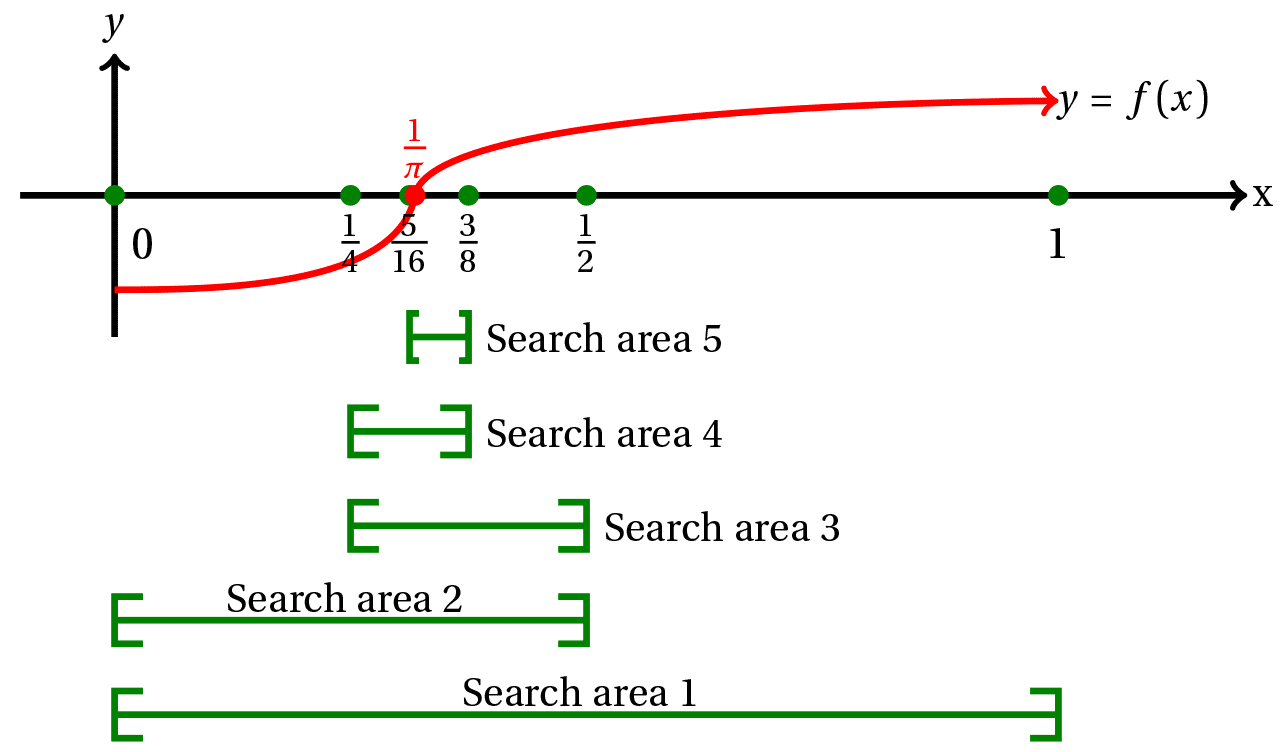

The method is applicable for numerically solving the equation $f\left(x\right)=0$ for the real variable $x$, when: 1). $f$ is a continuous function defined on an interval $\left\lbrack a,b\right\rbrack$ and 2). $f\left(a\right)$ and $f\left(b\right)$ have opposite signs.

Basic logic: if $a<b$ and $f\left(a\right)$ and $f\left(b\right)$ have different signs ($+/-$), there is at least one root in $\left(a,b\right)$. 

We can write an in-script root finding function (`bisection`) of the bisection method based on the following steps:

1. The inputs are: function $f$ (which we are looking for roots),  variables $a$ and $b$ to represent the interval $\left\lbrack a,b\right\rbrack$, and a positive threshold $h$ (if $\left|f\left(x_0 \right)\right|\le h$, then we think $x_0$ is a root). 

2. Select the middle point $c=\frac{\left(a+b\right)}{2}$, while $\left|f\left(c\right)\right|>h$, proceed to step 3. otherwise output $c$.

3. If $f\left(a\right)f\left(c\right)<0$, then update the variable $b$ by $b=c$ (push the right boundary from value $b$ to value $c$). Otherwise update the variable $a$ by $a=c$ (push the left boundary from value $a$ to value $c$).

4. Go back to step 2.

### ***In-class Exercise 1***

Write the in-script root finding function (`bisection`) in the code block at the end of this livescript. And test your function by running the following commands:

f = @(x) x.^2 -2;  % define function handle
rt = bisection(f,0,2,1e-8);
rt

***Question 1: what will happen if we set ***$h=0$***?***

***Question 2: what will happen if one of the input varibles ***$a$*** or ***$b$***, is one of the roots?***

***Question 3: does ***$c$*** have to be the middle point?***

***Question 4: what if ***$f\left(a\right)$*** and ***$f\left(b\right)$*** have the same sign?***

***Question 5: how do you know if the ***$h$ ***is small enough / the accuracy of the root is good enough?***

### ***In-class Exercise 2***

Modify the `bisection` (name the new one "`bisection_2`") so that your function can do the followings:

1) Display a message (it's your call) to the user if the initial input of search interval does not satisfy one of the following requirements: i) $a>b$, ii) $h\le 0$, iii) $f\left(a\right)$ and $f\left(b\right)$ have the same sign.

2) Add another input `l_thresh` to function, so that only when both the absolute function value is smaller than `f_thresh` and the length search interval is smaller than `l_thresh` will the program stop.

Test your function by running the following commands:

f = @(x) 1e-8*(x.^2 -2);  % define function handle
rt = bisection(f,0,2,1e-8);
rt

rt = 1

bisection_2(f,2,0,1e-8,1e-8) % a>b

Check inputs!


bisection_2(f,0,2,0,1e-8) % h = 0

Check inputs!


bisection_2(f,-2,2,1e-8,1e-8) % f(a) and f(b) have the same sign.

Check inputs!


bisection_2(f,0,2,1e-8,1e-8)

ans = 1.4142

## 2. Newton's Method

Core fomular: $x_{k+1} =x_k -\frac{f\left(x_k \right)}{f^{\prime } \left(x_k \right)}$

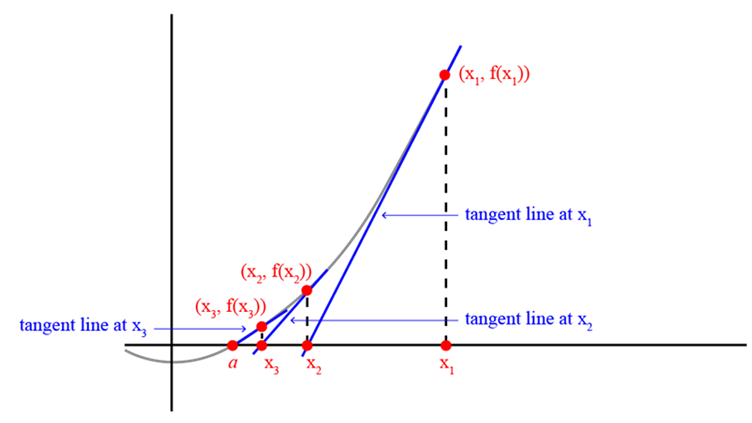

(source: [https://calcworkshop.com/derivatives/newtons-method/](https://calcworkshop.com/derivatives/newtons-method/) )

[Here](https://yasincapar.com/the-newton-raphson-method/) is an animation showing how Newton's method finds a root (numerically).

The function of tangent line at $x_1$: $y=f^{\prime } \left(x_1 \right)x+\left(f\left(x_1 \right)-f^{\prime } \left(x_1 \right)x_1 \right)$, when $y=0$ we have:

$x=\frac{f^{\prime } \left(x_1 \right)x_1 -f\left(x_1 \right)}{f^{\prime } \left(x_1 \right)}$, which is $x_2$. So $x_2 =x_1 -\frac{f\left(x_1 \right)}{f^{\prime } \left(x_1 \right)}$.

***Question 1: how to select ***$x_1$***? (usually we denote the first point as ***$x_0$***)***

***Question 2: if we know ***$f$*** and ***$f^{\prime }$***, what are other inputs that we need for Newton's method?***

f = @(x) x.^2 -2;
f_der = @(x) 2*x;
newton(f,f_der,1,1e-6)
f = @sin;
f_der = @cos;
newton(f,f_der,2,1e-6)

### ***In-class Exercise 3*** 

Modify the in-script function `newton`, so that your new function (`newton_2`) can do the followings:

1) In addition to $x$, the function has another output denoting the total number of steps.

2) Try to avoid the input of derivative function by calculating the numerical derivatives in Newton's method. To be more specific, make step size $h$ as the input to function and use central difference formula to approximate derivative in each step.

Test your function by running the following commands:

f = @(x) x.^2 -2;
[rt, n] = newton_2(f,20,1e-8,1e-8)

## 3. Other useful links

[https://www.youtube.com/watch?v=TZyyCARqJdo](https://www.youtube.com/watch?v=TZyyCARqJdo) 

[https://www.youtube.com/watch?v=cf_NK7NlWrs](https://www.youtube.com/watch?v=cf_NK7NlWrs) 

## 4. **Functions defined in this livescript**

% function x = bisection(f,a,b,f_thresh) % In-class Exercise 1

ans = 1.4142

ans = 3.1416

% function x = bisection_2(f,a,b,f_thresh,l_thresh) % In-class Exercise 2




function x = newton(f,f_der,x0,f_thresh)
    x = x0;

rt = 1.4142

n = 8

    while abs(f(x))>f_thresh
        x = x-f(x)/f_der(x);
    end

end

% function [x, n] = newton_2(f,x0,h,f_thresh) % In-class Exercise 3
